clear; close all;

## Lab 7

Harrison Robel; Partner: Karen Gong

### Event Optimization

When we have a background distribution there is often overlap between the background data and signal data. For our LHC data we are given many different features; each feature has a background and signal, most of which have overlap between distributions. When there is overlap in data or when the background is well understood it is often helpful in calculating significance to cut down the background in order to shrink the distribution and thus calculate a better significance.

A good example to show how cutting the data can affect the significance is by using the QCD data for the Higgs mass. The QCD background for mass has a large range and follows a Poisson distribution. The Higgs signal falls in the middle of the background distribution. Therefore if we know what range of mass we can find the Higgs in,(through theory or experiments) then we can narrow our search down and trim the background data. 

h5disp('qcd_100000_pt_1000_1200.h5')

HDF5 qcd_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'qcd_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


h5disp('higgs_100000_pt_1000_1200.h5')

HDF5 higgs_100000_pt_1000_1200.h5 
Group '/' 
    Dataset 'higgs_100000_pt_1000_1200' 
        Size:  14x100000
        MaxSize:  14x100000
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


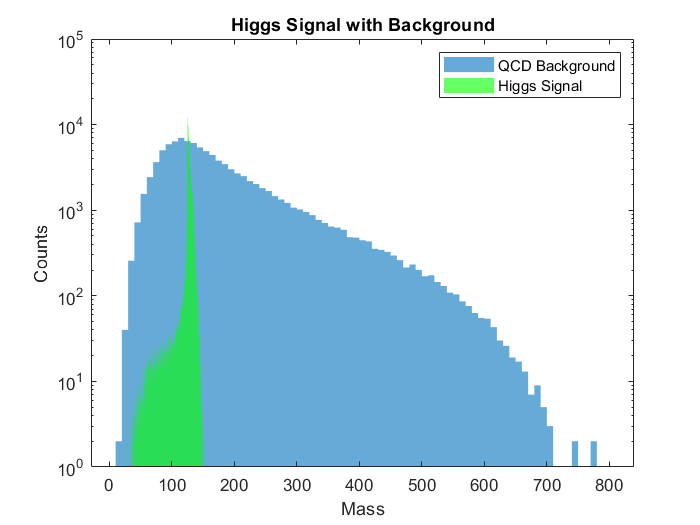

qcd = h5read('qcd_100000_pt_1000_1200.h5','/qcd_100000_pt_1000_1200');
higgs = h5read('higgs_100000_pt_1000_1200.h5','/higgs_100000_pt_1000_1200');

qcdpt = qcd(1,:);
qcdeta = qcd(2,:);
qcdphi = qcd(3,:);
qcdmass = qcd(4,:);
qcdee2 = qcd(5,:);
qcdee3 = qcd(6,:);
qcdd2 = qcd(7,:);
qcdangularity = qcd(8,:);
qcdt1 = qcd(9,:);
qcdt2 = qcd(10,:);
qcdt3 = qcd(11,:);
qcdt21 = qcd(12,:);
qcdt32 = qcd(13,:);
qcdKtDeltaR = qcd(12,:);

pt = higgs(1,:);
eta = higgs(2,:);
phi = higgs(3,:);
mass = higgs(4,:);
ee2 = higgs(5,:);
ee3 = higgs(6,:);
d2 = higgs(7,:);
angularity = higgs(8,:);
t1 = higgs(9,:);
t2 = higgs(10,:);
t3 = higgs(11,:);
t21 = higgs(12,:);
t32 = higgs(13,:);
KtDeltaR = higgs(14,:);

histogram(qcdmass,'EdgeColor','none','DisplayName','QCD Background')
set(gca,'Yscale','log')
hold on
histogram(mass,'EdgeColor','none','FaceColor','g','DisplayName','Higgs Signal')
legend("show")
hold on
xlabel('Mass')
ylabel('Counts')
title('Higgs Signal with Background')


prob5 = poisscdf(2050,2000);
sigma5 = norminv(prob5);

Before we cut the data we will evaluate the expected significance from the data without any cuts. From the untouched data we get a Higgs signficance of $\sigma =1\ldotp 1282$. This is not very significant. We can see from the graph above that the background is large and the Higgs mass spike is small relative to the background, the significance is also small. Checking the sigma to the given value of $\frac{N_{\textrm{Higgs}} }{\sqrt{N_{\textrm{QCD}} }}=1\ldotp 1180$ we can see that the two values are very similar which shows that the calculated sigma is what we would expect from an uncut data set.

sortedqcd = sort(qcdmass);
sortedhiggs = sort(mass);
Nhiggs = 50;
Nqcd = 2000;

cut1 = sortedqcd(1:90000);
Nhcut1 = Nhiggs * 1; %Have not cut into the higgs signal yet
Nqcdcut1 = Nqcd * .9;
Sigmacut1 = Nhcut1 / sqrt(Nqcdcut1)

Sigmacut1 = 1.1785


cut2 = sortedqcd(1:50000);
Nhcut2 = Nhiggs * 1; %Have not cut into the higgs signal yet
Nqcdcut2 = Nqcd * .5;
Sigmacut2 = Nhcut1 / sqrt(Nqcdcut2)

Sigmacut2 = 1.5811


cut3 = sortedqcd(10000:50000);
percentqcd1 = size(cut3,2) / 100000;
threshold = min(cut3);
sortedhiggs(sortedhiggs < threshold) = [];
percenthiggs1 = size(sortedhiggs,2) / 100000;
Nhcut3 = Nhiggs * percenthiggs1;
Nqcdcut3 = Nqcd * percentqcd1;
Sigmacut3 = Nhcut3 / sqrt(Nqcdcut3)

Sigmacut3 = 1.7479


cut4 = sortedqcd(30000:50000);
percentqcd1 = size(cut4,2) / 100000;
threshold = min(cut4);
sortedhiggs(sortedhiggs < threshold) = [];
percenthiggs1 = size(sortedhiggs,2) / 100000;
Nhcut4 = Nhiggs * percenthiggs1;
Nqcdcut4 = Nqcd * percentqcd1;
Sigmacut4 = Nhcut4 / sqrt(Nqcdcut4)

Sigmacut4 = 2.4182


cut5 = sortedqcd(36000:39000);
percentqcd1 = size(cut5,2) / 100000;
threshold = min(cut5);
sortedhiggs(sortedhiggs < threshold) = [];
percenthiggs = size(sortedhiggs,2) / 100000;
Nhcut5 = Nhiggs * percenthiggs;
Nqcdcut5 = Nqcd * percentqcd1;
Sigmacut5 = Nhcut5 / sqrt(Nqcdcut5)

Sigmacut5 = 5.9781


badcut = sortedqcd(40000:50000);
percentqcd = size(badcut,2) / 100000;
threshold = min(badcut);
sortedhiggs(sortedhiggs < threshold) = [];
percenthiggs1 = size(sortedhiggs,2) / 100000;
Nhbadcut = Nhiggs * percenthiggs1;
Nqcdbadcut = Nqcd * percentqcd;
Sigmabadcut = Nhbadcut / sqrt(Nqcdbadcut)

Sigmabadcut = 0.5602

Now we can cut the mass data in order to make the mass spike more prominent and give us a better significance. If we start to cut the background data but keep the signal data range untouched we can see that we can start to improve the significance. However at some point our cuts may start to include some of the signal data and therefore our signal will also be cut down; this still creates a stronger significance than if we were not to have any cuts at all. From optimizing the cuts we can get a cut where we remove 97% of the background data but still manage to keep 92% of the Higgs data therefore we can get a sigma of 5.9781. We can also see a situation where we ended up cutting too much off and started cutting into the Higgs data. The bad example is one where we cut off 90% of the background data but was left with only 16% of the Higgs data and therefore only got a sigma of 0.5602.

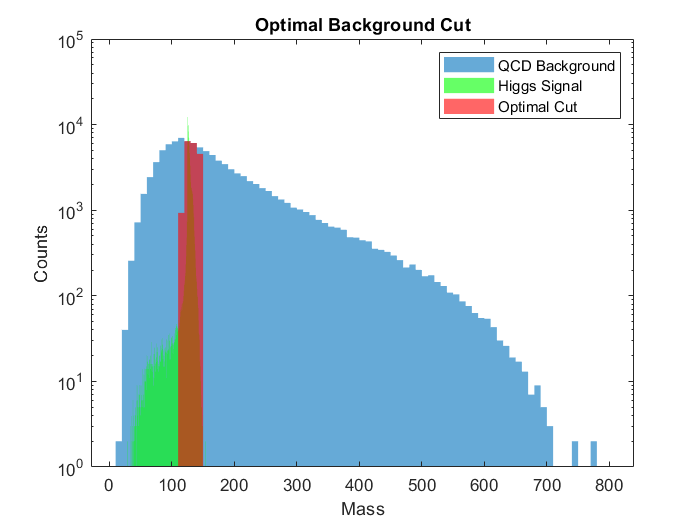

histogram(sortedqcd(32000:50000),'FaceColor','r','EdgeColor','none','BinWidth',10,'DisplayName','Optimal Cut')
xlabel('Mass')
ylabel('Counts')
title('Optimal Background Cut')

After cutting mass and making an optimal selection range for mass feature we can go through the remaining features and see if there are any other features that can are also optimizable.

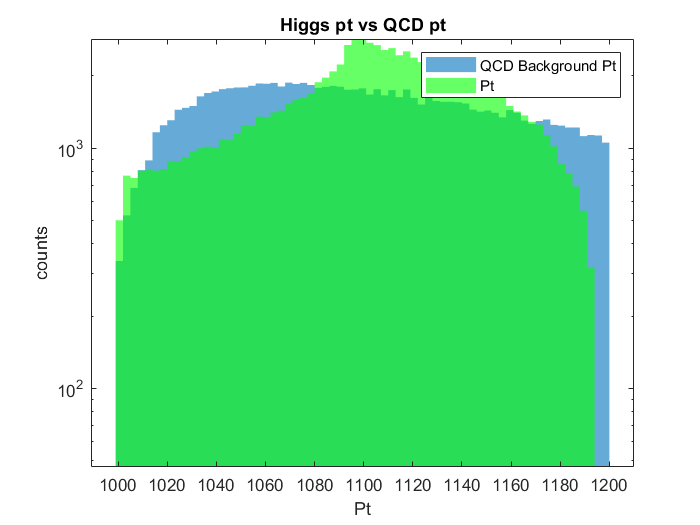

close all
histogram(qcdpt,'EdgeColor','none','DisplayName','QCD Background Pt')
set(gca,'Yscale','log')
hold on
histogram(pt,'EdgeColor','none','DisplayName','Pt','FaceColor','g')
legend('Show')
xlabel('Pt')
ylabel('counts')
title('Higgs pt vs QCD pt')
hold on

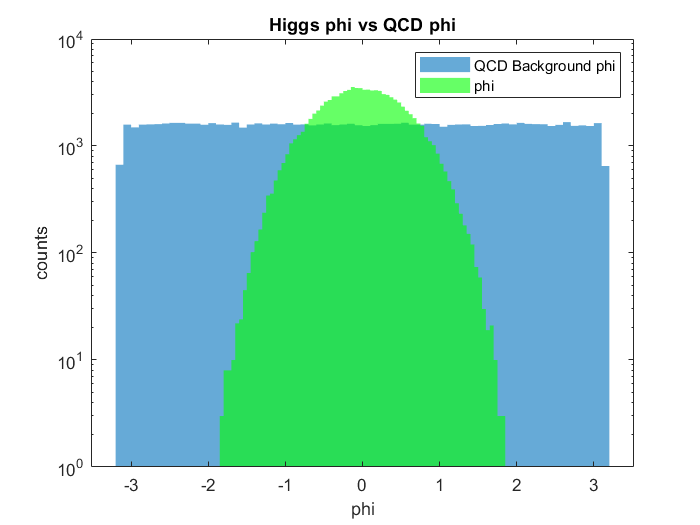

close all
histogram(qcdphi,'EdgeColor','none','DisplayName','QCD Background phi')
set(gca,'Yscale','log')
hold on
histogram(eta,'EdgeColor','none','DisplayName','phi','FaceColor','g')
legend('Show')
xlabel('phi')
ylabel('counts')
title('Higgs phi vs QCD phi')
hold on

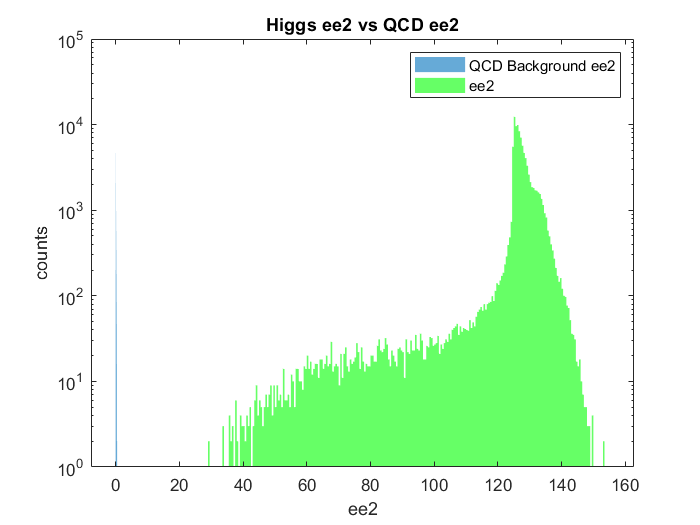

close all
histogram(qcdee2,'EdgeColor','none','DisplayName','QCD Background ee2')
set(gca,'Yscale','log')
hold on
histogram(mass,'EdgeColor','none','DisplayName','ee2','FaceColor','g')
legend('Show')
xlabel('ee2')
ylabel('counts')
title('Higgs ee2 vs QCD ee2')
hold on

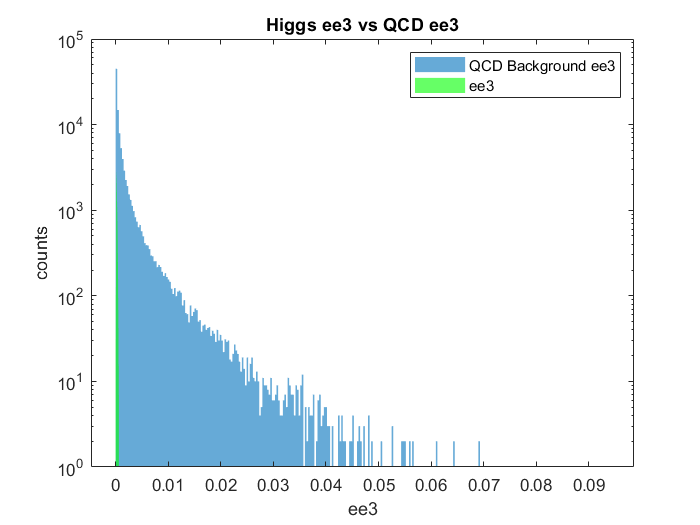

close all
histogram(qcdee3,'EdgeColor','none','DisplayName','QCD Background ee3')
set(gca,'Yscale','log')
hold on
histogram(ee3,'EdgeColor','none','DisplayName','ee3','FaceColor','g')
legend('Show')
xlabel('ee3')
ylabel('counts')
title('Higgs ee3 vs QCD ee3')
hold on

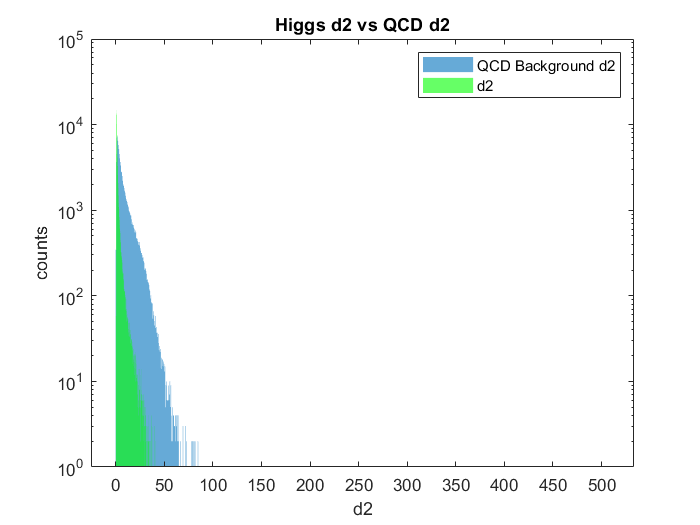

close all
histogram(qcdd2,'EdgeColor','none','DisplayName','QCD Background d2')
set(gca,'Yscale','log')
hold on
histogram(d2,'EdgeColor','none','DisplayName','d2','FaceColor','g')
legend('Show')
xlabel('d2')
ylabel('counts')
title('Higgs d2 vs QCD d2')
hold on

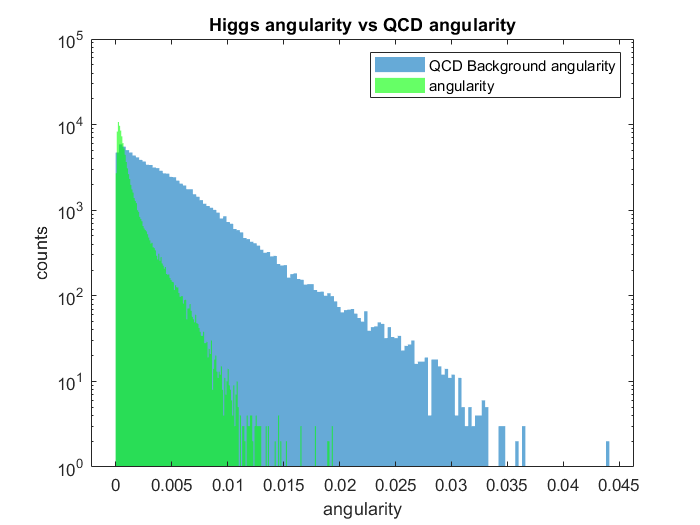

close all
histogram(qcdangularity,'EdgeColor','none','DisplayName','QCD Background angularity')
set(gca,'Yscale','log')
hold on
histogram(angularity,'EdgeColor','none','DisplayName','angularity','FaceColor','g')
legend('Show')
xlabel('angularity')
ylabel('counts')
title('Higgs angularity vs QCD angularity')
hold on

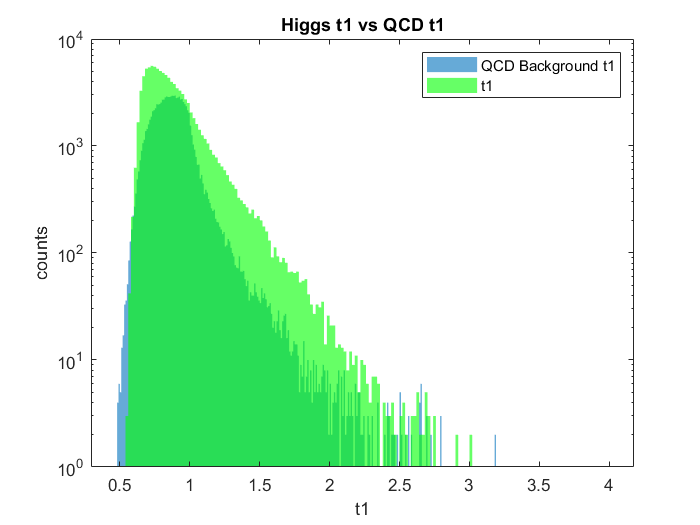

close all
histogram(qcdt1,'EdgeColor','none','DisplayName','QCD Background t1')
set(gca,'Yscale','log')
hold on
histogram(t1,'EdgeColor','none','DisplayName','t1','FaceColor','g')
legend('Show')
xlabel('t1')
ylabel('counts')
title('Higgs t1 vs QCD t1')
hold on

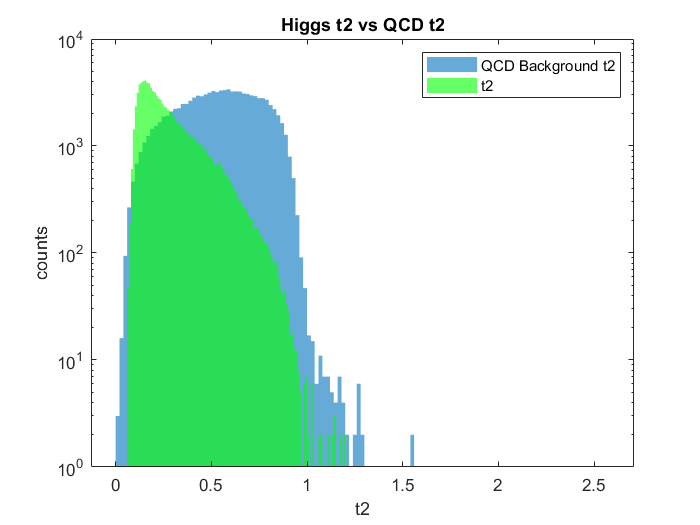

close all
histogram(qcdt2,'EdgeColor','none','DisplayName','QCD Background t2')
set(gca,'Yscale','log')
hold on
histogram(t2,'EdgeColor','none','DisplayName','t2','FaceColor','g')
legend('Show')
xlabel('t2')
ylabel('counts')
title('Higgs t2 vs QCD t2')
hold on

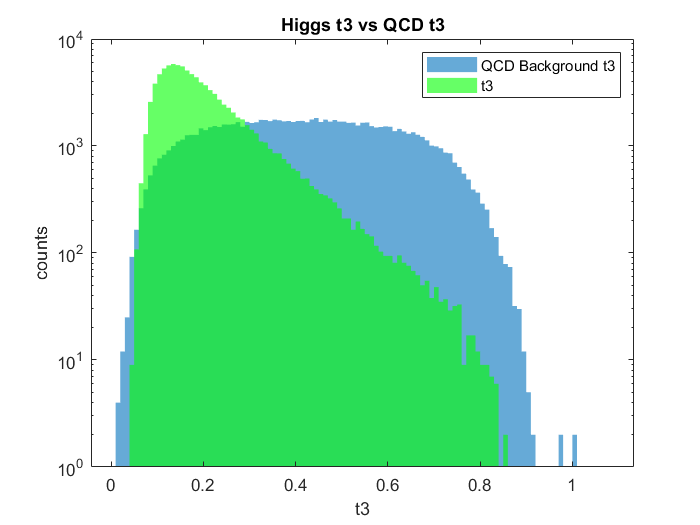

close all
histogram(qcdt3,'EdgeColor','none','DisplayName','QCD Background t3')
set(gca,'Yscale','log')
hold on
histogram(t3,'EdgeColor','none','DisplayName','t3','FaceColor','g')
legend('Show')
xlabel('t3')
ylabel('counts')
title('Higgs t3 vs QCD t3')
hold on

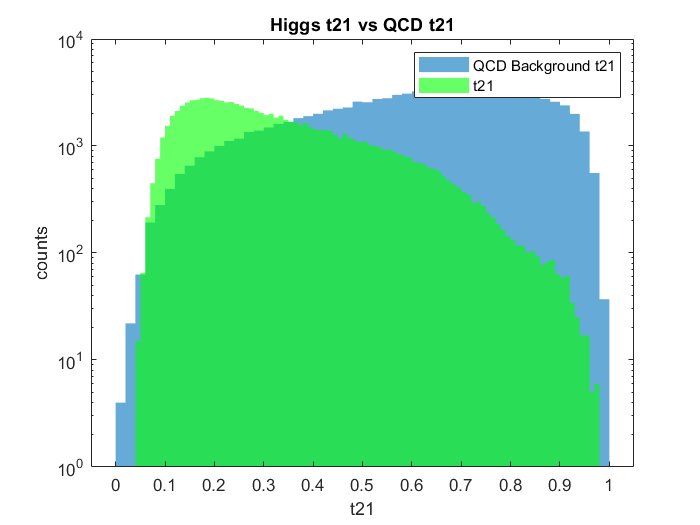

close all
histogram(qcdt21,'EdgeColor','none','DisplayName','QCD Background t21')
set(gca,'Yscale','log')
hold on
histogram(t21,'EdgeColor','none','DisplayName','t21','FaceColor','g')
legend('Show')
xlabel('t21')
ylabel('counts')
title('Higgs t21 vs QCD t21')
hold on

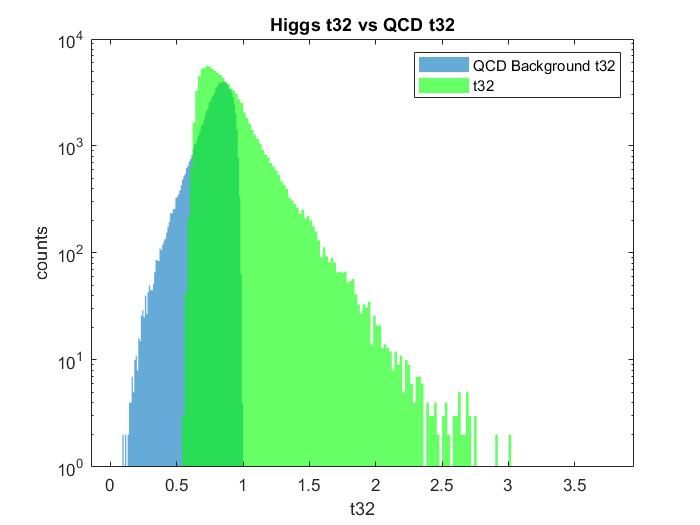

close all
histogram(qcdt32,'EdgeColor','none','DisplayName','QCD Background t32')
set(gca,'Yscale','log')
hold on
histogram(t1,'EdgeColor','none','DisplayName','t32','FaceColor','g')
legend('Show')
xlabel('t32')
ylabel('counts')
title('Higgs t32 vs QCD t32')
hold on

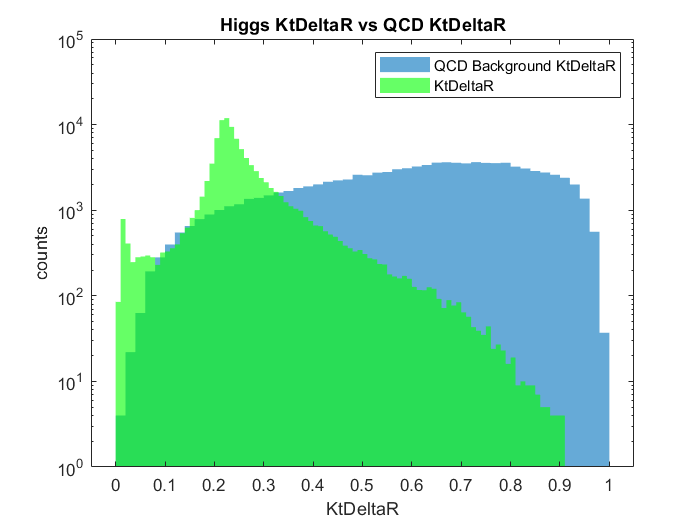

close all
histogram(qcdKtDeltaR,'EdgeColor','none','DisplayName','QCD Background KtDeltaR')
set(gca,'Yscale','log')
hold on
histogram(KtDeltaR,'EdgeColor','none','DisplayName','KtDeltaR','FaceColor','g')
legend('Show')
xlabel('KtDeltaR')
ylabel('counts')
title('Higgs KtDeltaR vs QCD KtDeltaR')
hold on

After looking at all the different graphs of all the features in the data set there are a few that look like they can be optimized. The features that I am looking for is a signal that locally has more counts than the background data. The two graphs that fit this critiera are the KtDeltaR and the Phi data. Both these graphs have signals that raise above the graph.

sortedKtqcd = sort(qcdKtDeltaR);
sortedKt = sort(KtDeltaR);

cut5 = sortedKtqcd(3000:7000);
percentqcd5 = size(cut5,2) / 100000;
threshold = min(cut5);
sortedKt(sortedKt < threshold) = [];
percenthiggs5 = size(sortedKt,2) / 100000;
Nhcut5 = Nhiggs * percenthiggs5;
Nqcdcut5 = Nqcd * percentqcd5;
Sigmacut5 = Nhcut1 / sqrt(Nqcdcut5)

Sigmacut5 = 5.5895


sortedphiqcd = sort(qcdphi);
sortedphi = sort(phi);

cut6 = sortedphiqcd(30000:35000);
percentqcd6 = size(cut6,2) / 100000;
threshold = min(cut6);
sortedphi(sortedphi < threshold) = [];
percenthiggs6 = size(sortedKt,2) / 100000;
Nhcut6 = Nhiggs * percenthiggs6;
Nqcdcut6 = Nqcd * percentqcd6;
Sigmacut6 = Nhcut6 / sqrt(Nqcdcut6)

Sigmacut6 = 4.5506

After optimizing these two cuts the sigma started at 1.118 and now we got the KtDeltaR sigma of 5.0876 and a Phi sigma of 4.5506. With both of these cuts optimized and the mass cut optimized we can use these statistics to evaluate the real Higgs data after we unblind ourselves. 

## Lab 8

Now that we have created a package of anaylsis from the simulated data we can reveal the "real" Higgs data to ourselves. We have an optimized cut for mass KtDeltaR and phi. With these optimized cuts we can see if we have a significant higgs detection. 

close all
h5disp('data_highLumi_pt_1000_1200.h5')

HDF5 data_highLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribut

h5disp('data_lowLumi_pt_1000_1200.h5')

HDF5 data_lowLumi_pt_1000_1200.h5 
Group '/' 
    Attributes:
        'TITLE':  ''
        'CLASS':  'GROUP'
        'VERSION':  '1.0'
        'PYTABLES_FORMAT_VERSION':  '2.1'
    Group '/data' 
        Attributes:
            'TITLE':  ''
            'CLASS':  'GROUP'
            'VERSION':  '1.0'
            'pandas_type':  'frame'
            'pandas_version':  '0.15.2'
            'encoding':  'UTF-8'
            'errors':  'strict'
            'ndim':  2
            'axis0_variety':  'regular'
            'axis1_variety':  'regular'
            'nblocks':  1
            'block0_items_variety':  'regular'
        Dataset 'axis0' 
            Size:  14
            MaxSize:  14
            Datatype:   H5T_STRING
                String Length: 10
                Padding: H5T_STR_NULLTERM
                Character Set: H5T_CSET_ASCII
                Character Type: H5T_C_S1
            ChunkSize:  []
            Filters:  none
            FillValue:  '          '
            Attribute

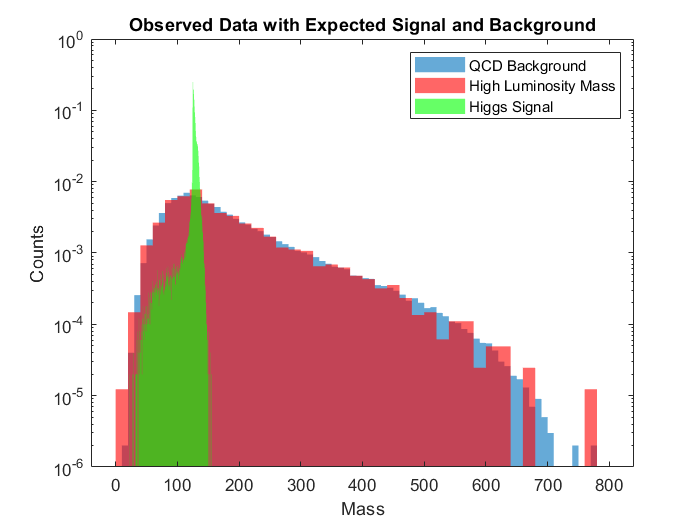

nameshigh = h5read('data_highLumi_pt_1000_1200.h5','/data/block0_items');
datahigh = h5read('data_highLumi_pt_1000_1200.h5','/data/block0_values');
nameslow = h5read('data_lowLumi_pt_1000_1200.h5','/data/block0_items');
datalow = h5read('data_lowLumi_pt_1000_1200.h5','/data/block0_values');

pthigh = datahigh(1,:);
etahigh = datahigh(2,:);
phihigh = datahigh(3,:);
masshigh = datahigh(4,:);
ee2high = datahigh(5,:);
ee3high = datahigh(6,:);
d2high = datahigh(7,:);
angularityhigh = datahigh(8,:);
t1high = datahigh(9,:);
t2high = datahigh(10,:);
t3high = datahigh(11,:);
t21high = datahigh(12,:);
t32high = datahigh(13,:);
KtDeltaRHigh = datahigh(14,:);

histogram(qcdmass,'EdgeColor','none','DisplayName','QCD Background','normalization','pdf')
hold on
histogram(masshigh,'EdgeColor','none','DisplayName','High Luminosity Mass','FaceColor','r','normalization','pdf')
set(gca,'Yscale','log')
hold on
histogram(mass,'EdgeColor','none','FaceColor','g','normalization','pdf','DisplayName','Higgs Signal')
legend("show")
hold on
xlabel('Mass')
ylabel('Counts')
title('Observed Data with Expected Signal and Background')

From our normalized graph of the QCD background, simulated Higgs signal and the now included high luminosity mass data we can see that the mass data follows the background quite closely. However there does not seem to be a very large spike where the Higgs signal is. One important thing to note is that with the simulated data we have an even amount of background data and Higgs data (100000). Because of this the signal is going to be much more prominent in the simulated background. In practice there should be much more background data than Higgs counts. There is a small bump at the Higgs mass which may or may not be significant.

Nhiggs = 102;
Nback = 4077;

cuthiggs = Nhiggs * percenthiggs1;
cutback = Nback * percentqcd1;

sigma1 = cuthiggs/sqrt(cutback)

sigma1 = 1.4611

From the values given $N_{\mathrm{higgs}} =50$ and $N_{\mathrm{qcd}} =2000$ we can expect a single Higgs in every 40 counts. That gives us 102 counts for the 4077 data points we have in the high luminosity data. After applying our cut and caclulating our significance we can see that from our mass data we do not have a very significant result. This could be due to cutting too much Higgs data off.

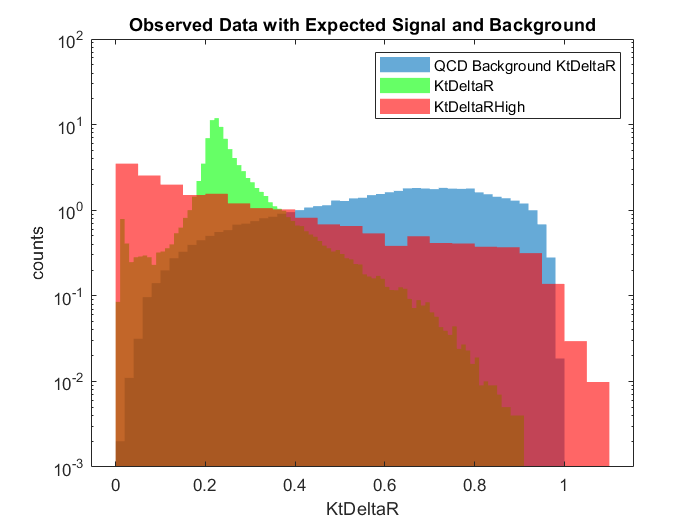

close all
histogram(qcdKtDeltaR,'EdgeColor','none','DisplayName','QCD Background KtDeltaR','normalization','pdf')
set(gca,'Yscale','log')
hold on
histogram(KtDeltaR,'EdgeColor','none','DisplayName','KtDeltaR','FaceColor','g','normalization','pdf')
hold on
histogram(KtDeltaRHigh,'EdgeColor','none','FaceColor','r','normalization','pdf')
legend('Show')
xlabel('KtDeltaR')
ylabel('counts')
title('Observed Data with Expected Signal and Background')
hold on 


cuthiggs2 = Nhiggs * percenthiggs5;
cutback2 = Nback * percentqcd5;

sigma2 = cuthiggs2/sqrt(cutback2)

sigma2 = 7.2693

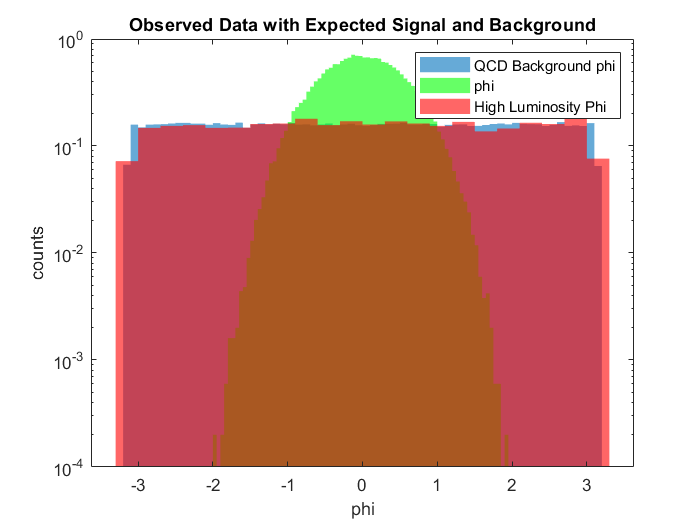

close all
histogram(qcdphi,'EdgeColor','none','DisplayName','QCD Background phi','Normalization','pdf')
set(gca,'Yscale','log')
hold on
histogram(eta,'EdgeColor','none','DisplayName','phi','FaceColor','g','Normalization','pdf')
legend('Show')
xlabel('phi')
ylabel('counts')
title('Observed Data with Expected Signal and Background')
hold on
histogram(phihigh,'EdgeColor','none','FaceColor','r','DisplayName','High Luminosity Phi','Normalization','pdf')


cuthiggs3 = Nhiggs * percenthiggs6;
cutback3 = Nback * percentqcd6;

sigma3 = cuthiggs3/sqrt(cutback3)

sigma3 = 6.5020

After applying the cuts for KtDeltaR and for Phi we get a sigma of 7.293 and 6.5020. These results are much more significant than the result that we got from the mass cuts. This could show that our mass cut is too narrow and removed too many Higgs counts.

Next step is to look at our low luminosity data and run the same analysis.

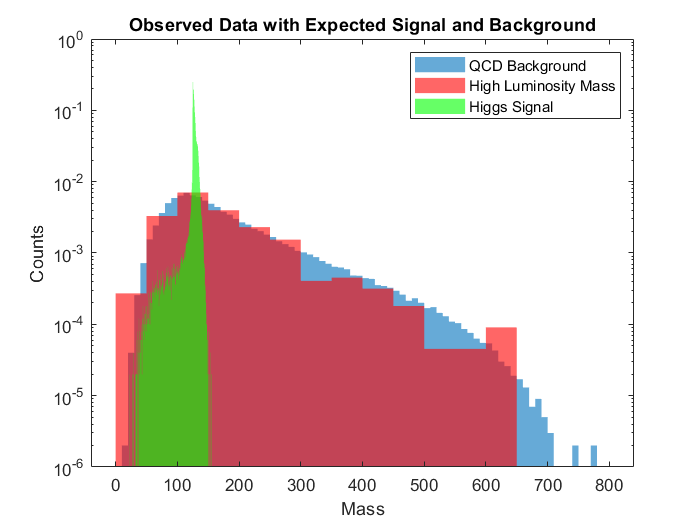

ptlow = datalow(1,:);
etalow = datalow(2,:);
philow = datalow(3,:);
masslow = datalow(4,:);
ee2low = datalow(5,:);
ee3low = datalow(6,:);
d2low = datalow(7,:);
angularitylow = datalow(8,:);
t1low = datalow(9,:);
t2low = datalow(10,:);
t3low = datalow(11,:);
t21low = datalow(12,:);
t32low = datalow(13,:);
KtDeltaRlow = datalow(14,:);

close all
histogram(qcdmass,'EdgeColor','none','DisplayName','QCD Background','normalization','pdf')
hold on
histogram(masslow,'EdgeColor','none','DisplayName','High Luminosity Mass','FaceColor','r','normalization','pdf')
set(gca,'Yscale','log')
hold on
histogram(mass,'EdgeColor','none','FaceColor','g','normalization','pdf','DisplayName','Higgs Signal')
legend("show")
hold on
xlabel('Mass')
ylabel('Counts')
title('Observed Data with Expected Signal and Background')


Nhiggs = 11;
Nback = 442 ;

cuthiggs4 = Nhiggs * percenthiggs1;
cutback4 = Nback * percentqcd1;

sigma4 = cuthiggs4/sqrt(cutback4)

sigma4 = 0.4786

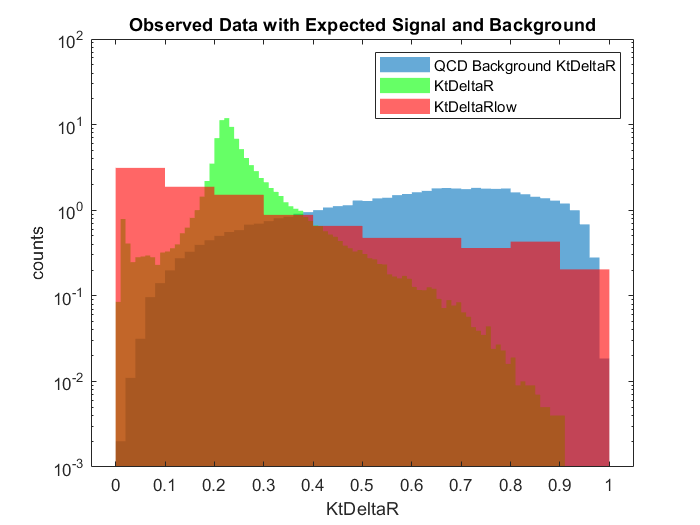

close all
histogram(qcdKtDeltaR,'EdgeColor','none','DisplayName','QCD Background KtDeltaR','normalization','pdf')
set(gca,'Yscale','log')
hold on
histogram(KtDeltaR,'EdgeColor','none','DisplayName','KtDeltaR','FaceColor','g','normalization','pdf')
hold on
histogram(KtDeltaRlow,'EdgeColor','none','FaceColor','r','normalization','pdf')
legend('Show')
xlabel('KtDeltaR')
ylabel('counts')
title('Observed Data with Expected Signal and Background')


cuthiggs5 = Nhiggs * percenthiggs5;
cutback5 = Nback * percentqcd5;

sigma5 = cuthiggs5/sqrt(cutback5)

sigma5 = 2.3809

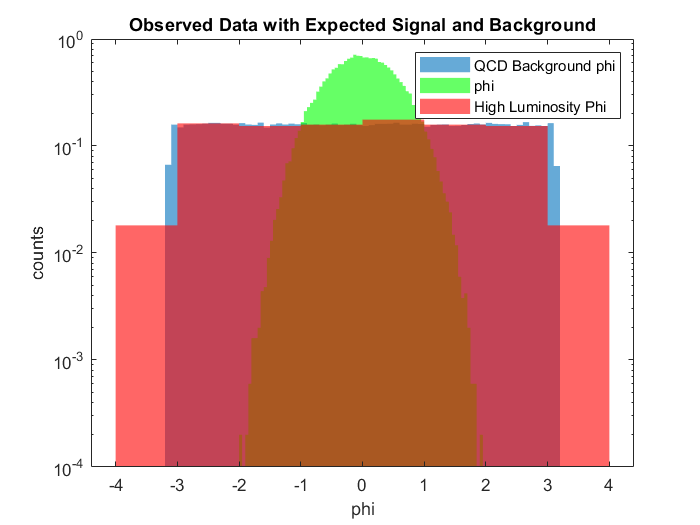

close all
histogram(qcdphi,'EdgeColor','none','DisplayName','QCD Background phi','Normalization','pdf')
set(gca,'Yscale','log')
hold on
histogram(eta,'EdgeColor','none','DisplayName','phi','FaceColor','g','Normalization','pdf')
legend('Show')
xlabel('phi')
ylabel('counts')
title('Observed Data with Expected Signal and Background')
hold on
histogram(philow,'EdgeColor','none','FaceColor','r','DisplayName','High Luminosity Phi','Normalization','pdf')


cuthiggs6 = Nhiggs * percenthiggs6;
cutback6 = Nback * percentqcd6;

sigma6 = cuthiggs6/sqrt(cutback6)

sigma6 = 2.1296

After our analysis we can see that we do not have very a significant signal in the low luminosity data with a mass sigma of 0.4786 KtDeltaR of 2.3809 and a phi sigma of 2.1296. This shows that it is very important in LHC data to gather as much counts as possible in order to reach a high significance. 

However we can still gather some science from our observation; we can use the observed counts to calculate our 95% confidence interval and set an upper/lower limit on where the Higgs could be.

Nexpected = 50;
Nobserved = 11;

upperexp = poissinv(.84,50)

upperexp = 57

lowerexp = poissinv(0.16,50)

lowerexp = 43


upperobs = poissinv(.84,11)

upperobs = 14

lowerobs = poissinv(0.16,11)

lowerobs = 8

From out calculations of the upper and lower limit we can see that the expected higgs signal is $N_{\mathrm{higgs}} =50\pm 7$ and for the observed signal we have $N_{\mathrm{higgs}} =11\pm 3$. 